# Thermodynamics of N-Schlogl

%specify roots
roots = [ 1 2 3]

roots =      1     2     3


%get rate from roots
poly = -1;
x = sym('x');
for i = 1:size(roots,2)
    poly = poly*(x-roots(i));
end

poly_func = matlabFunction(poly)

poly_func = function_handle with value:
    @(x)-(x-1.0).*(x-2.0).*(x-3.0)


%Get rate cosntants 
C = coeffs(poly)

$$C = \left(\begin{array}{cccc} 6 & -11 & 6 & -1 \end{array}\right)$$

k_const = abs(C)

$$k\_const = \left(\begin{array}{cccc} 6 & 11 & 6 & 1 \end{array}\right)$$

%get forward and backward rates
rplus = 0;
rmin = 0;

for i = 1:size(k_const,2)
    if mod(i,2) == 0
        rmin = rmin + k_const(i)*x^(i-1);
    else 
        rplus = rplus + k_const(i)*x^(i-1);
    end
end
rpoly = rplus - rmin;

%verify rate from roots and rate cosntants is the same
simplify(rpoly-poly)

$$ans = 0$$

%rate across each reaction
r_rxn = [];
%potential change across each reaction
G_rxn = [];

for i = 1:size(k_const,2)/2
     r_rate = k_const(2*i - 1)*x^(2*i-2) -  k_const(2*i)*x^(2*i-1);
    r_rxn = [r_rxn; r_rate];
    G_rxn = [G_rxn; log(rmin/rplus)*r_rate];
end
r_rxn

$$r\_rxn = \left(\begin{array}{c} 6-11\,x\\ 6\,x^{2}-x^{3} \end{array}\right)$$

G_rxn

$$G\_rxn = \left(\begin{array}{c} -\log\left(\frac{x^{3}+11\,x}{6\,x^{2}+6}\right)\,\left(11\,x-6\right)\\ \log\left(\frac{x^{3}+11\,x}{6\,x^{2}+6}\right)\,\left(6\,x^{2}-x^{3}\right) \end{array}\right)$$

r_rxn_func = matlabFunction(r_rxn)

r_rxn_func = function_handle with value:
    @(x)[x.*-1.1e+1+6.0;x.^2.*6.0-x.^3]


G_rxn_func = matlabFunction(G_rxn)

G_rxn_func = function_handle with value:
    @(x)[-log((x.*1.1e+1+x.^3)./(x.^2.*6.0+6.0)).*(x.*1.1e+1-6.0);log((x.*1.1e+1+x.^3)./(x.^2.*6.0+6.0)).*(x.^2.*6.0-x.^3)]


%total dissipation
diss = log(rmin/rplus)*poly;
diss_func = matlabFunction(diss);

%intrinsic dissipation near equilibrium
diss_eq_1 = log(x/roots(1))*poly;
diss_eq_3 = log(x/roots(3))*poly;
diss_func_1 = matlabFunction(diss_eq_1);
diss_func_3 = matlabFunction(diss_eq_3);

%plots
x_arr = max(0,min(roots)):abs(min(roots))/100: max(abs(roots));

%rate plots
figure()
hold on
label_lst = 1:size(r_rxn,1);
for i = 1:size(r_rxn,2)
    plot(x_arr,r_rxn_func(x_arr))
end
plot(x_arr,poly_func(x_arr),'k')
yline(0,'--')
%ylim([-0.5 0.5])
label_lst =[label_lst "total"]

label_lst = 1×3 string array
    "1"    "2"    "total"


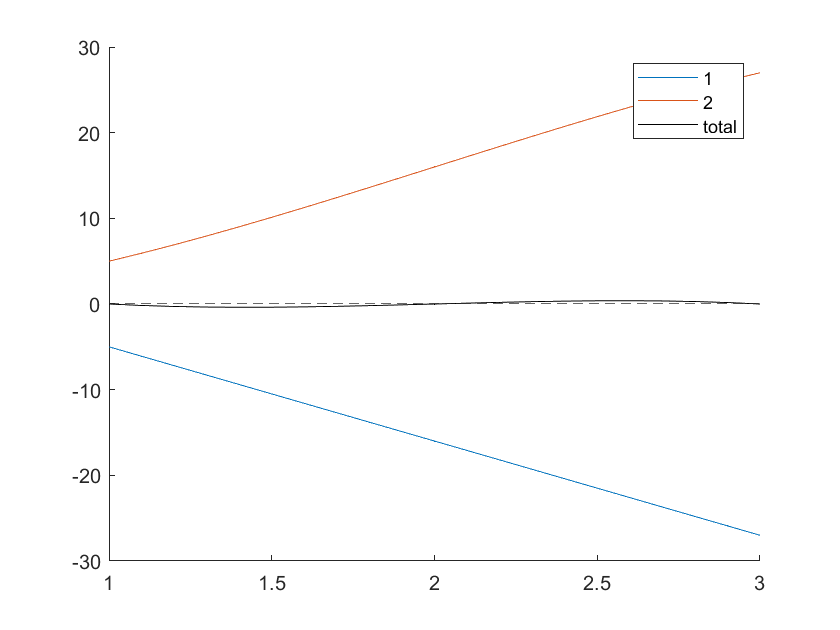

legend(string(label_lst))

%dissipation plots
figure()
hold on
label_lst = 1:size(r_rxn,1);
for i = 1:size(r_rxn,2)
    plot(x_arr,G_rxn_func(x_arr))
end
plot(x_arr,diss_func(x_arr),'k')
yline(0,'--')
%ylim([-0.5 0.5])
label_lst =[label_lst "total"]

label_lst = 1×3 string array
    "1"    "2"    "total"


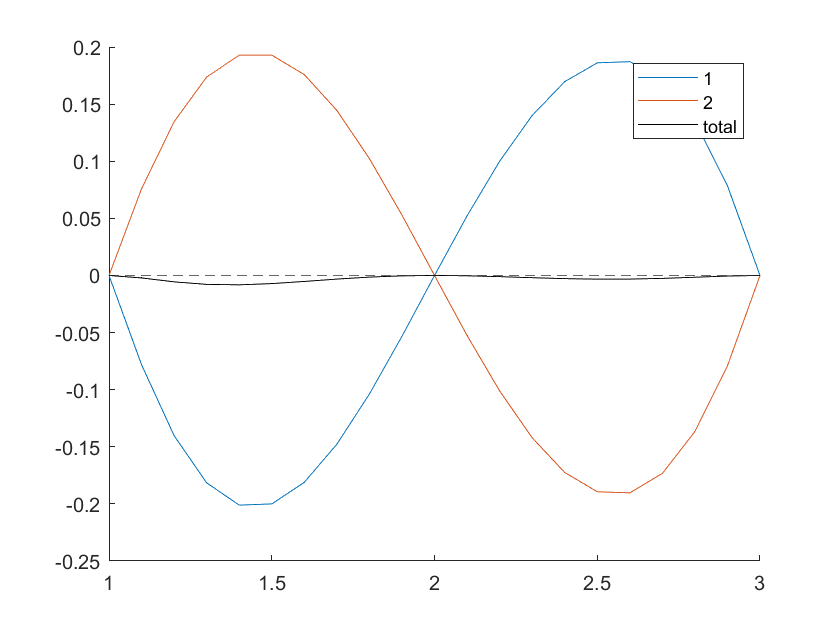

legend(string(label_lst))

%dissipation plots against internal near attractor
figure()
hold on
%label_lst = 1:size(r_rxn,1);
plot(x_arr,diss_func(x_arr),'k')
plot(x_arr,diss_func_1(x_arr),'r')
plot(x_arr,diss_func_3(x_arr),'b')
yline(0,'--')
%ylim([-0.5 0.5])
label_lst =[ "LDF" "eq1" "eq3"]

label_lst = 1×3 string array
    "LDF"    "eq1"    "eq3"


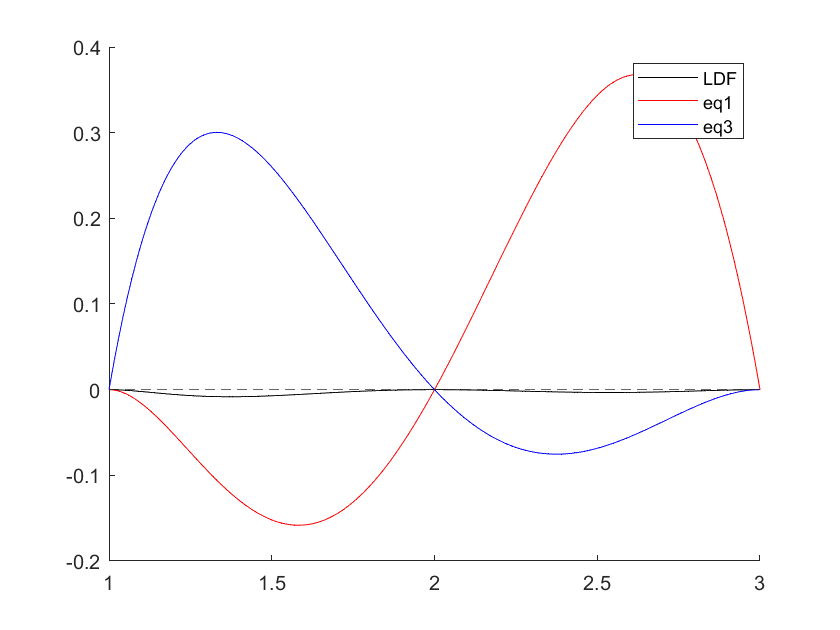

legend(string(label_lst))

label_lst = 1:size(r_rxn,1)

label_lst =      1     2
